%% TwoTankSystem

clear all
close all
clc

%% Simulation paramters
SIM_TIME = 1000; % simulation time [sec]
STEP_SIZE = 0.05; % fundamental sampling time for running simulations [sec]

%% Model parameters
At = 0.785; % [m^2]
Dv = 2.66; % [m^(1/2)/s]
C0 = 0.056; % [[m^(5/2)/s]]
ka = 0.004; % [m^3/(V*s)]
kh = 2; % [V/m]
kt = 0.1; % [V/C]

% Input and disturbance working point
uw0 = 5; % hot water valve [V]
u10 = uw0;
uc0 = 5; % cold water valve [V]
u20 = uc0;
Av0 = 0.0122; % area of outlet valve [m^2]
v10 = Av0;
Tw0 = 60; % temperature of the hot water [C]
v20 = Tw0;
Tc0 = 30; % temperature of the cold water [C]
v30 = Tc0;

% Simulate the system to evaluate the stationary state in connection with
% the chosen values of input and disturbances
x0 = [1.5,0.2,40,20]'; % initial conditions for the state variables x0 = [H1,H2,T1,T2]'
sim('TwoTankSystem_SteadyState',SIM_TIME,[],[])
x0 = xFinal' % simulated steady state condition

x0 =     2.0291
    1.5190
   45.0000
   45.0000


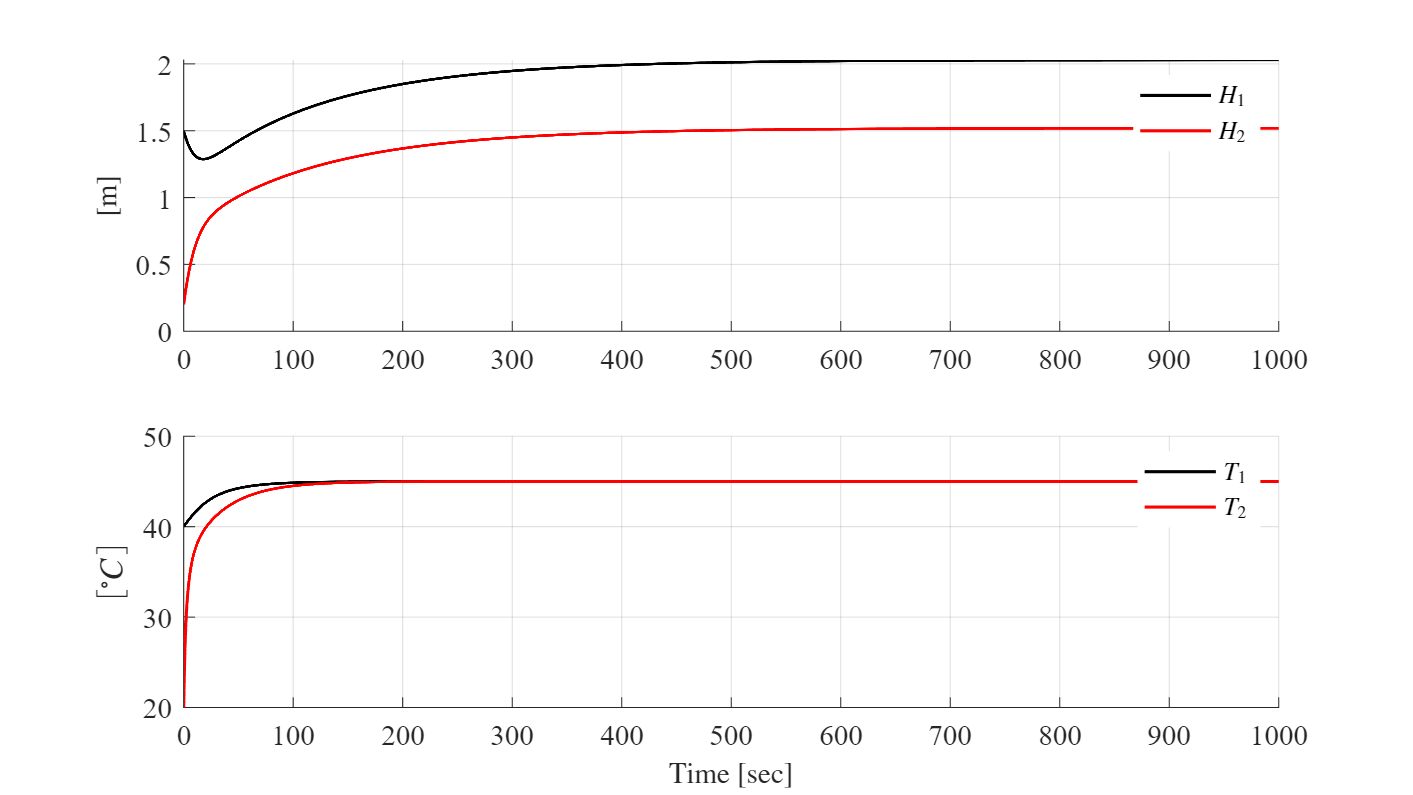


% Plot of state responses
t = logsout.getElement('H1').Values.Time;
H1 = logsout.getElement('H1').Values.Data;
H2 = logsout.getElement('H2').Values.Data;
Tm1 = logsout.getElement('T1').Values.Data;
Tm2 = logsout.getElement('T2').Values.Data;

figure('units','normalized','outerposition',[0 0 1 1],'PaperOrientation','landscape','Renderer','Painter') 
hf1 = subplot(2,1,1); set(hf1,'FontName','times','FontSize',14)
hold on, grid on
plot(t,H1,'k',t,H2,'r','LineWidth',1.5)
ylabel('[m]','FontName','times','FontSize',14,'Interpreter','latex')
leg1 = legend('$H_1$','$H_2$','Location','NorthEast');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex','box','off')
hf2 = subplot(2,1,2); set(hf2,'FontName','times','FontSize',14)
hold on, grid on
plot(t,Tm1,'k',t,Tm2,'r','LineWidth',1.5)
xlabel('Time [sec]','FontName','times','FontSize',14,'Interpreter','latex')
ylabel('$[^\circ C]$','FontName','times','FontSize',16,'Interpreter','latex')
leg2 = legend('$T_1$','$T_2$','Location','NorthEast');
set(leg2,'FontName','times','FontSize',12,'Interpreter','latex','box','off')

    
%% Numerically linearize the nonlinear model around the stationary state

% Numerical linearization of a nonlinear system implemented in Simulink can
% be achieved through the command LINMOD (read help)
u0 = [u10 u20 v10 v20 v30]';
[A,B,C,D] = linmod('TwoTankSystem_Linearize',x0,u0);
Bv = B(:,3:5);
B = B(:,1:2);
Dvv = D(:,3:5);
D = D(:,1:2);
x0_lin = zeros(size(A,1),1);

% Present the linearized model
disp('Numerically linearized model of the Two Tank System')

Numerically linearized model of the Two Tank System


disp('matrix A')

matrix A


disp(A)

    -0.049939     0.049939            0            0
     0.049939    -0.066711            0            0
  -1.3762e-13            0    -0.025112            0
   1.0636e-12   -1.778e-12     0.033544    -0.033544



disp('matrix B')

matrix B


disp(B)

    0.0050955    0.0050955
            0            0
     0.037668    -0.037668
            0            0



disp('matrix Bv')

matrix Bv


disp(Bv)

            0            0            0
      -4.1762            0            0
            0     0.012556     0.012556
            0            0            0



disp('matrix C')

matrix C


disp(C)

            0            2            0            0
            0            0            0          0.1



disp('matrix D')

matrix D


disp(D)

     0     0
     0     0



disp('matrix Dv')

matrix Dv


disp(Dvv)

     0     0     0
     0     0     0




%% Discretize the system

% Choose the sampling time
lambda = eig(A); % eigenvalues
tau = 1./abs(lambda); % time constants

Ts = 1; % sampling time [sec] chosen approximately 10 times smaller than the smallest time constant
[F,G] = c2d(A,B,Ts);
[~,Gv] = c2d(A,Bv,Ts);

% Present the discretized linear model
disp('Discretized linear model of the Two Tank System')

Discretized linear model of the Two Tank System


disp('matrix F')

matrix F


disp(F)

      0.95247      0.04713            0            0
      0.04713      0.93664            0            0
  -1.3261e-13  -3.2786e-15       0.9752            0
   9.7609e-13  -1.6667e-12     0.032575      0.96701



disp('matrix G')

matrix G


disp(G)

    0.0049724    0.0049724
   0.00012242   0.00012242
     0.037199    -0.037199
   0.00061956  -0.00061956



disp('matrix Gv')

matrix Gv


disp(Gv)

     -0.10033            0            0
      -4.0416            0            0
   4.6181e-15       0.0124       0.0124
   3.5562e-12   0.00020652   0.00020652



disp('matrix C')

matrix C


disp(C)

            0            2            0            0
            0            0            0          0.1



disp('matrix D')

matrix D


disp(D)

     0     0
     0     0



disp('matrix Dv')

matrix Dv


disp(Dv)

         2.66




% Compare the discretized linear model with the continuous time nonlinear
% model
u0 = [u10 u20 v10 v20 v30]';
v0 = u0(3:5,1);
u0 = u0(1:2,1);
y0 = C*x0;

% Step changes in inputs and disturbances
uw1 = 1.1*uw0;
Tw = 100;
uc1 = 0.9*uc0;
Tc = 400;
Av1 = 1.05*Av0;
Tv = 700;
Tw1 = 1.1*Tw0;
Te1 = 1100;
Tc1 = 1.2*Tc0;
Te2 = 1500;

%% System stability

lambda_OL = eig(A); % open loop eigenvalues
if sum(real(lambda_OL) < 0) == size(A,1)
    disp('Open loop system is asymptotically stable')
elseif sum(real(lambda_OL) < 0) < size(A,1)
    tmp = size(A,1) - sum(real(lambda_OL) < 0);
    if sum(real(lambda_OL) > 0) >= 1 || tmp > 1
        disp('Open loop system is unstable')
    elseif sum(real(lambda_OL) > 0) == 0 && tmp == 1
        disp('Open loop system is marginally stable')
    end
end

Open loop system is asymptotically stable


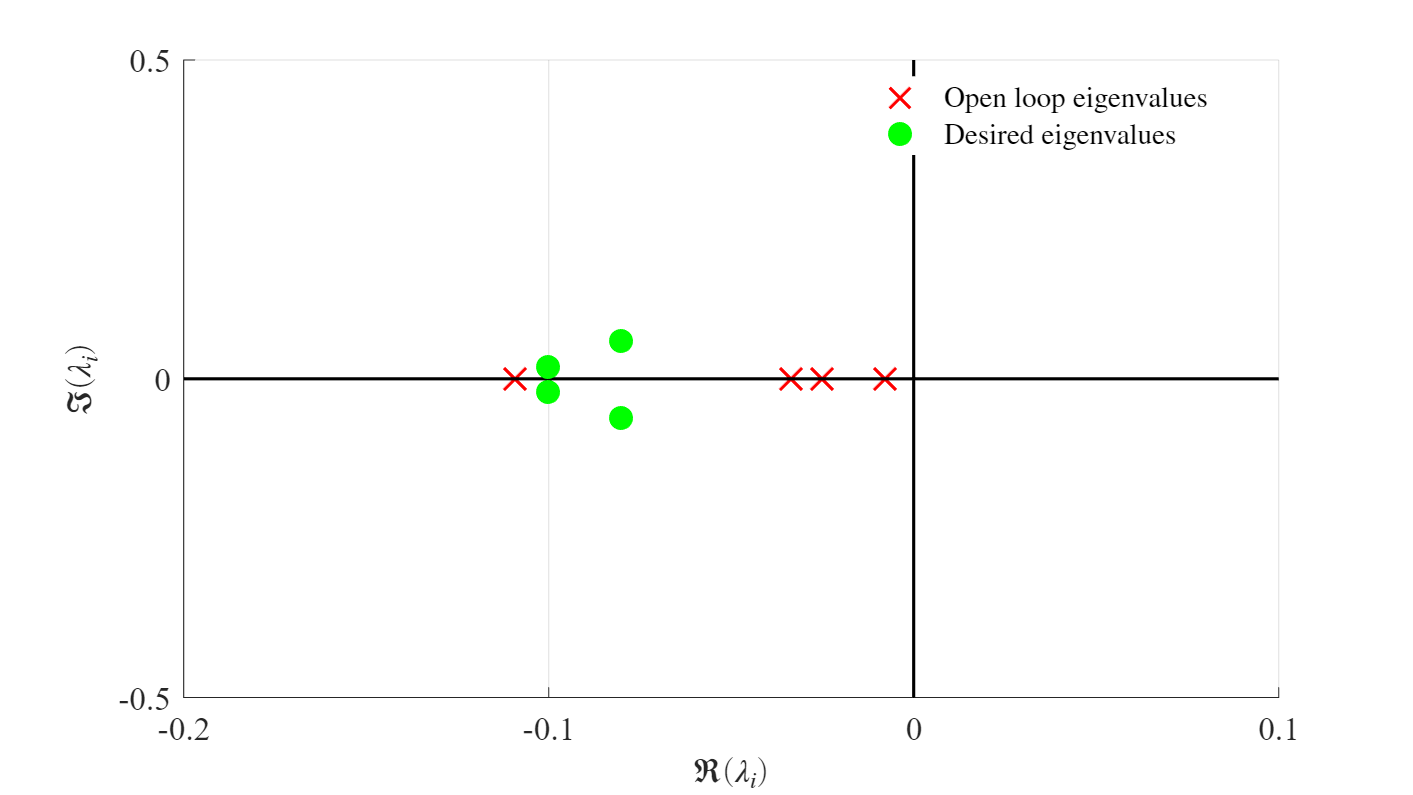

TwoTankSys = ss(A,B,C,D);
[w,z] = damp(TwoTankSys);

figure('units','normalized','outerposition',[0 0 1 1],'PaperOrientation','landscape','Renderer','Painter') 
h1 = axes; set(h1,'FontName','times','FontSize',16)
hold on, grid on
h1 = plot(real(lambda_OL),imag(lambda_OL),'x','MarkerSize',15,'MarkerEdgeColor','r','LineWidth',1.5);
line([floor(min(real(lambda_OL))) ceil(max(real(lambda_OL)))+0.1],[0 0],'Color','k','LineWidth',1.5)
line([0 0],[floor(min(imag(lambda_OL)))-1 ceil(max(imag(lambda_OL)))+1],'Color','k','LineWidth',1.5)
xlabel('$\Re(\lambda_i)$','FontName','times','FontSize',16,'Interpreter','latex')
ylabel('$\Im(\lambda_i)$','FontName','times','FontSize',16,'Interpreter','latex')
xlim([-0.2 0.1])
ylim([-0.5 0.5])

lambda_CL_des = [-0.1+0.02*1i -0.1-0.02*1i -0.08+0.06*1i -0.08-0.06*1i]'; % desired eigenvalues for the closed loop system
h2 = plot(real(lambda_CL_des),imag(lambda_CL_des),'o','MarkerSize',10,'MarkerEdgeColor','g','MarkerFaceColor','g','LineWidth',1.5);
leg = legend([h1 h2],'Open loop eigenvalues','Desired eigenvalues');
set(leg,'FontName','times','FontSize',14,'Interpreter','latex','box','off')

    
%% Controllability analysis

Mc = ctrb(A,B);
if rank(Mc) == size(A,1)
    disp('Open loop system is controllable')
else
    dimCs = size(A,1) - rank(Mc); % dimension of controllability subspace
    disp('Open loop system is not controllable and the controllability subspace has dimension ',dimCs)
end

Open loop system is controllable



%% Observability analysis

Mo = obsv(A,C);
if rank(Mo) == size(A,1)
    disp('Open loop system is controllable')
else
    dimOs = size(A,1) - rank(Mo); % dimension of controllability subspace
    disp('Open loop system is not observable and the observability subspace has dimension ',dimOs)
end

Open loop system is controllable
